# Exercise 5: MIMO OFDM

The provided MATLAB code simulates a basic communication system using OFDM modulation. The simulation involves the generation of a payload data, modulation of data, transmission over a channel, and the estimation of the channel's response.

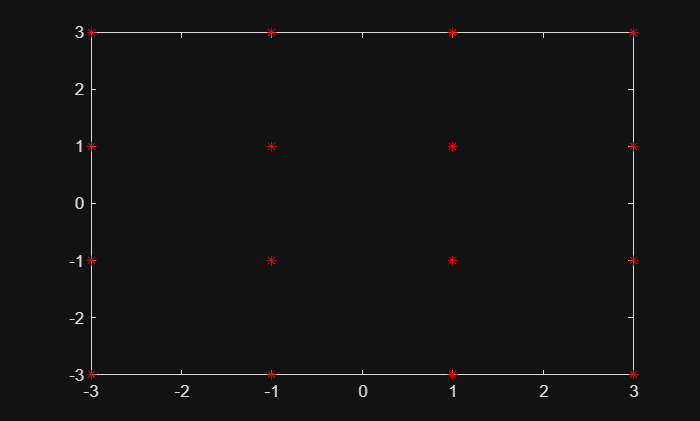

clear variables;

bps = 4;    % Bits per symbol
M = 2^bps;  % 16QAM
n_FFT = 1024; % Number of FFT bins
n_SCoccupied = 601; % Number of occupied subcarriers
n_CP = 72;    % CP length

% Loop over different SNR values
SNRdB_vec = -10:2:30; % SNR values to loop over
nSymbols = 10; % Number of simulations for each SNR value

% Bit stream generation and modulation
txdata = randi([0 1],n_SCoccupied*bps*nSymbols,1);
txsymbols = qammod(txdata,M,InputType="bit"); % apply qammod

% Reshape to txgrid
txgrid = reshape(txsymbols,n_SCoccupied,nSymbols);

% Observe the constellation diagram
figure; 
plot(txgrid,'*r')

**Virtual Subcarrier Insertion**

The guard subcarriers play a critical role in maintaining the integrity and performance of OFDM systems by guarding against both time-domain and frequency-domain distortions, ultimately improving the system's resilience to various channel impairments.

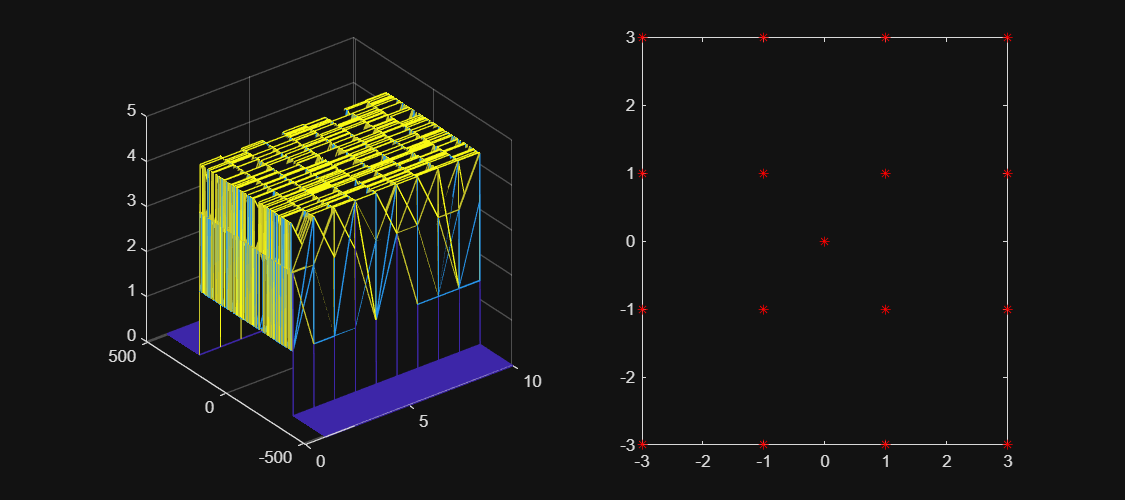

% Insert Guard subcarriers
txgrid_withGB = insertGaurdSubcarriers(txgrid,n_SCoccupied,n_FFT);    

% Observe the IFFT Input
figure('Position',[0 0 900 400]); 
subplot(1,2,1);
mesh(1:nSymbols,-n_FFT/2:n_FFT/2-1,abs(txgrid_withGB));
subplot(1,2,2);
plot(txgrid_withGB,'*r')

**Create a Time-Domain Signal**

% Apply IFFT
txgrid_inTime = ifft(txgrid_withGB);

**Add Cyclic Prefix**

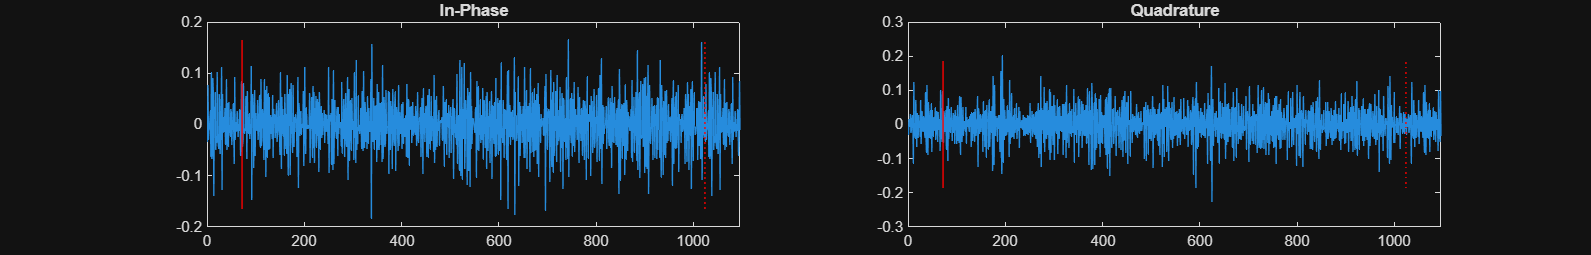

addCP = true;
if addCP
    % add a cyclic prefix for tx
    txgrid_withCP = insertCP(txgrid_inTime,n_CP);    

    % Observe the result on a random signal
    figure('Position',[0 0 2500 400]); 
    subplot(1,2,1)
    plot(real(txgrid_withCP(:,randi(nSymbols))))
    peakval1 = max(abs(real(txgrid_withCP(:,randi(nSymbols)))));
    hold on; plot([n_CP n_CP],[-peakval1 peakval1],'r'); plot([n_FFT n_FFT],[-peakval1 peakval1],':r')   
    title('In-Phase')
    xlim([0 n_FFT+n_CP]);
    subplot(1,2,2)
    plot(imag(txgrid_withCP(:,randi(nSymbols))))
    peakval2 = max(abs(imag(txgrid_withCP(:,randi(nSymbols)))));
    hold on; plot([n_CP n_CP],[-peakval2 peakval2],'r'); plot([n_FFT n_FFT],[-peakval2 peakval2],':r')    
    title('Quadrature')
    xlim([0 n_FFT+n_CP]);
else
    txgrid_withCP = txgrid_inTime;
end


% Vectorize the OFDM symbols in form of a single time domain signal
txout = txgrid_withCP(:);

**Channel Multipath Single Input Multiple Output (SIMO) 1x2**

Define the channel parameters and then filter the transmit signal through the channel

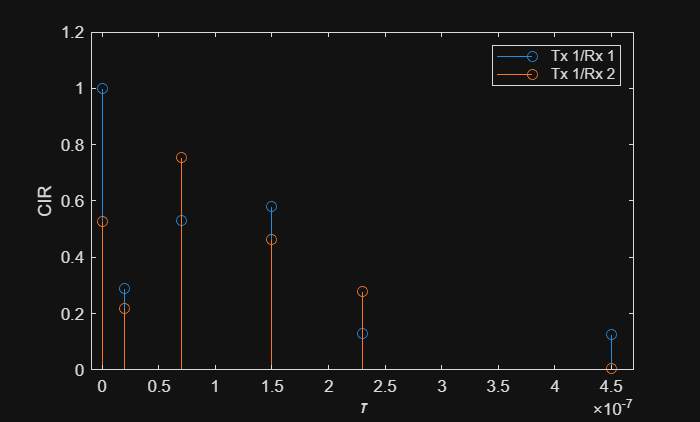

% Doppler frequency
v = 80;                                      % UE velocity in km/h
fc = 1.8e9;                                   % carrier frequency in Hz
fs = 15.46e6;                                 % Sampling rate
c = physconst('lightspeed');                  % speed of light in m/s
maxDopplerShift = (v/3.6)/(c/fc);             % UE max Doppler frequency in Hz

% Number of antennas on Tx and Rx
n_TXantenna = 1;
n_RXantenna = 2;

% Multipath channel parameters
delayVector = [0 20 70 150 230 450]*1e-9;  % discrete delays for 6 path fading channel in s

% Initialize arrays
gainVector = cell(n_RXantenna, n_TXantenna);
chan_obj = cell(n_RXantenna, n_TXantenna);
ch_puretone = cell(n_RXantenna, n_TXantenna);
pathGains = cell(n_RXantenna, n_TXantenna);

for ch_Rx_idx = 1:n_RXantenna
    for ch_Tx_idx = 1:n_TXantenna
        % Use fixed gains so both antennas are equally strong on average
        gainVector{ch_Rx_idx, ch_Tx_idx} = [0 -1 -2 -3 -6 -9];
        chan_obj{ch_Rx_idx, ch_Tx_idx} = comm.RayleighChannel('SampleRate', fs, ...
            'PathDelays', delayVector, 'AveragePathGains', gainVector{ch_Rx_idx, ch_Tx_idx}, ...
            'MaximumDopplerShift', maxDopplerShift, 'PathGainsOutputPort', 1);
    
        % Send a pure tone to find the CIR filter coefficients
        [ch_puretone{ch_Rx_idx, ch_Tx_idx}, pathGains{ch_Rx_idx, ch_Tx_idx}] = chan_obj{ch_Rx_idx, ch_Tx_idx}([complex(1,0); zeros(n_CP,1)]);
    end
end

% Observe the true CIR
figure;
for ch_idx = 1:n_RXantenna
    stem(delayVector, abs(pathGains{ch_idx, 1}(1,:)))
    hold on;
end
hold off;
ylabel('CIR'); xlabel('\tau')
xlim([-1e-8 470e-9])
legend('Tx 1/Rx 1','Tx 1/Rx 2');

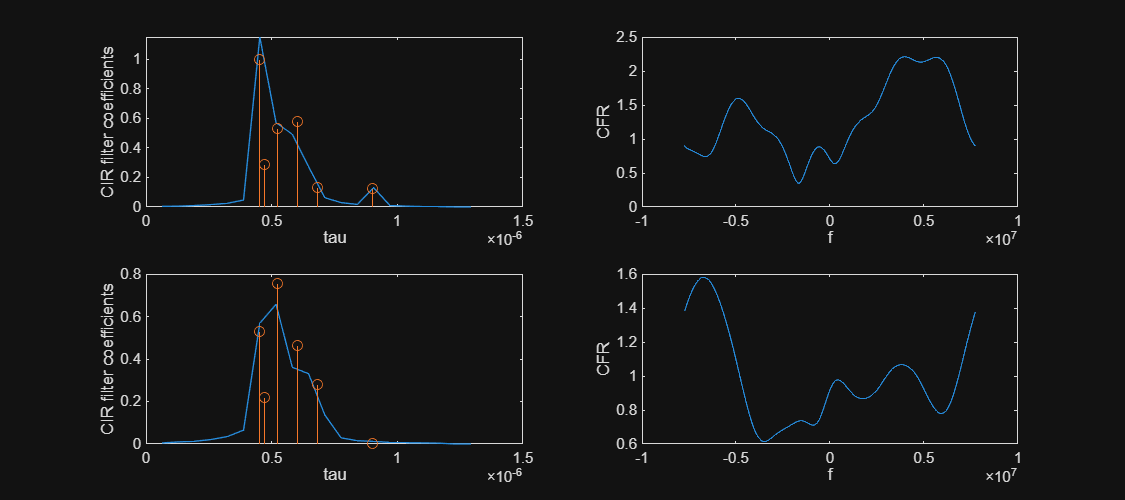


% Observe the CIR filter coefficients and CFR that the pure tone experiences
figure('Position',[0 0 900 400]);
for ch_idx = 1:n_RXantenna
    chan_filter_synced{ch_idx, 1} = circshift(ch_puretone{ch_idx, 1},-1); % Synchronization
    chan_filter_ZeroPadded{ch_idx, 1} = [chan_filter_synced{ch_idx, 1}(1:40); zeros(1024-n_CP-1,1); chan_filter_synced{ch_idx, 1}(41:end)];
end

subplot(2,2,1)
plot((1:20)/fs,abs(chan_filter_ZeroPadded{1, 1}(1:20)))
ylabel('CIR filter coefficients')
xlabel('tau')
hold on; stem(delayVector + 7/fs, abs(pathGains{1, 1}(1,:)))

subplot(2,2,2)
plot(linspace(-fs/2,fs/2,n_FFT),abs(fft(chan_filter_ZeroPadded{1, 1})))
ylabel('CFR')
xlabel('f')

subplot(2,2,3)
plot((1:20)/fs,abs(chan_filter_ZeroPadded{2, 1}(1:20)))
ylabel('CIR filter coefficients')
xlabel('tau')
hold on; stem(delayVector + 7/fs, abs(pathGains{2, 1}(1,:)))

subplot(2,2,4)
plot(linspace(-fs/2,fs/2,n_FFT),abs(fft(chan_filter_ZeroPadded{2, 1})))
ylabel('CFR')
xlabel('f')


% Apply the channel to the transmit signal
for ch_Rx_idx = 1:n_RXantenna
    for ch_Tx_idx = 1:n_TXantenna
        [chwaveform{ch_Rx_idx, ch_Tx_idx}, pathGains{ch_Rx_idx, ch_Tx_idx}] = chan_obj{ch_Rx_idx, ch_Tx_idx}(txout);
    end
end

**Perfect Channel Estimation**

Apply perfect channel estimation knowing the characteristics of the communication channel through which the signal travels. 

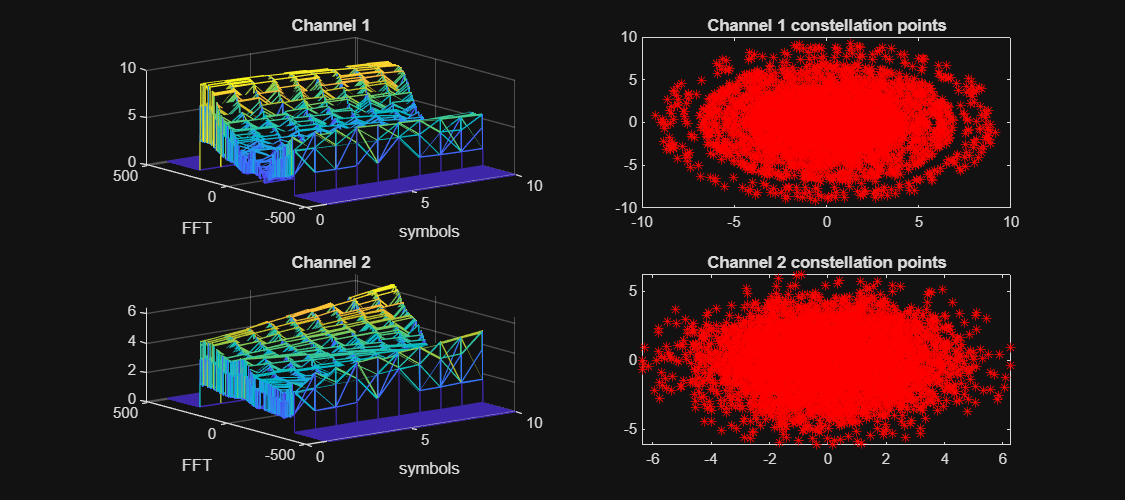

rxgrid_withGB = cell(n_RXantenna, n_TXantenna);

for ch_Rx_idx = 1:n_RXantenna
    for ch_Tx_idx = 1:n_TXantenna
        % Reshape the receive signal
        chwaveform_withCP = reshape(chwaveform{ch_Rx_idx, ch_Tx_idx}, [n_FFT+n_CP nSymbols]);
        
        % Remove the CP
        chwaveform_noCP = removeCP(chwaveform_withCP,n_CP);
        
        % OFDM Demodulation (apply FFT)
        rxgrid_withGB{ch_Rx_idx, ch_Tx_idx} = fft(chwaveform_noCP);
    end
end

% Observe the receive signal grid
figure('Position',[0 0 900 400]);
subplot(2,2,1)
mesh(1:nSymbols,-n_FFT/2:n_FFT/2-1,abs(rxgrid_withGB{1, 1}));
xlabel('symbols'); ylabel('FFT'); title('Channel 1');

subplot(2,2,2);
plot(rxgrid_withGB{1, 1},'*r');
title('Channel 1 constellation points');

subplot(2,2,3)
mesh(1:nSymbols,-n_FFT/2:n_FFT/2-1,abs(rxgrid_withGB{2, 1}));
xlabel('symbols'); ylabel('FFT'); title('Channel 2');

subplot(2,2,4)
plot(rxgrid_withGB{2, 1},'*r');
title('Channel 2 constellation points');

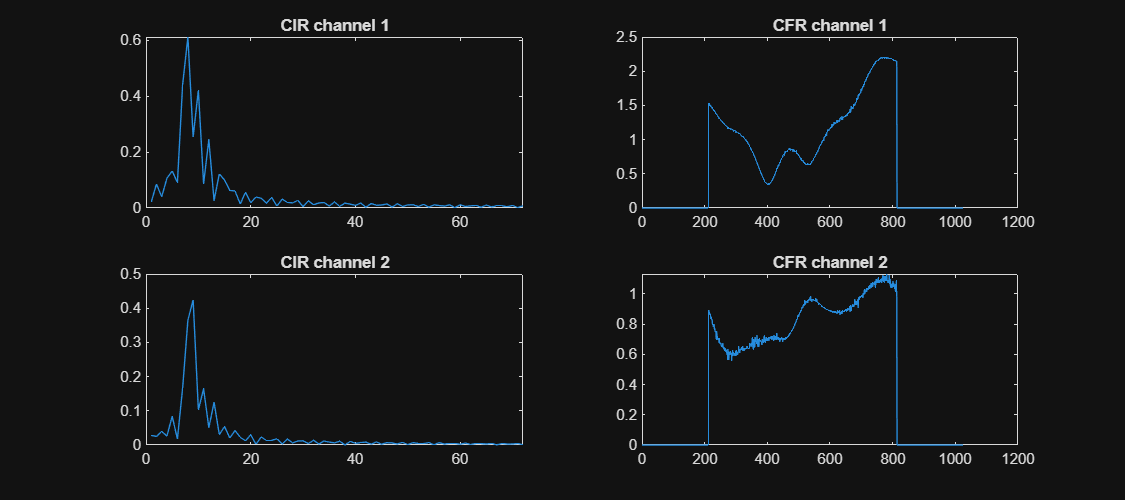


for ch_Rx_idx = 1:n_RXantenna
    for ch_Tx_idx = 1:n_TXantenna
        % Remove Guardbands
        rxgrid = removeGaurdSubcarriers(rxgrid_withGB{ch_Rx_idx, ch_Tx_idx},n_SCoccupied,n_FFT);
        
        % Apply Least Squares channel estimation on noiseless symbols
        Hhat_perfect{ch_Rx_idx, ch_Tx_idx} = rxgrid./txgrid;
    
        Hhat_perfect_withGB{ch_Rx_idx, ch_Tx_idx} = insertGaurdSubcarriers(Hhat_perfect{ch_Rx_idx, ch_Tx_idx},n_SCoccupied,n_FFT);
    end
end

% Observe the channel response
figure('Position',[0 0 900 400]);
subplot(2,2,1)
plot(abs(ifft(Hhat_perfect_withGB{1, 1}(:,1))))
xlim([0 n_CP]); title('CIR channel 1');

subplot(2,2,2) 
plot(abs(Hhat_perfect_withGB{1, 1}(:,1))); title('CFR channel 1');

subplot(2,2,3)
plot(abs(ifft(Hhat_perfect_withGB{2, 1}(:,1))))
xlim([0 n_CP]); title('CIR channel 2');

subplot(2,2,4) 
plot(abs(Hhat_perfect_withGB{2, 1}(:,1))); title('CFR channel 2');

**Simulation 1: SIMO 1x2**

Simulation of a static channel through AWGN for various SNR values. Correspondingly, equalizing the receive signal. 

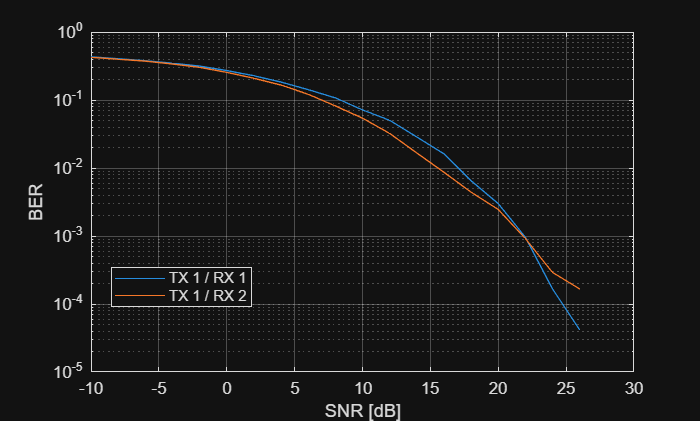

totalBER = cell(length(SNRdB_vec),1);
rxgrid = [];
totalBER_avg = zeros(1,length(SNRdB_vec));

for SNR_idx = 1:length(SNRdB_vec)
    for ch_Rx_idx = 1:n_RXantenna
        for ch_Tx_idx = 1:n_TXantenna            
            % Additive white Gaussian noise
            chwaveform_in = awgn(chwaveform{ch_Rx_idx, ch_Tx_idx},SNRdB_vec(SNR_idx),"measured"); 
    
            % Reshape the receive signal
            chwaveform_withCP = reshape(chwaveform_in, [n_FFT+n_CP nSymbols]);
    
            % Remove the CP
            chwaveform_noCP = removeCP(chwaveform_withCP,n_CP);
            
            % OFDM Demodulation (apply FFT)
            rxgrid_withGB = fft(chwaveform_noCP);        
    
            % Remove Guardbands
            rxgrid{SNR_idx}{ch_Rx_idx, ch_Tx_idx} = removeGaurdSubcarriers(rxgrid_withGB,n_SCoccupied,n_FFT);
    
            ApplyEqualizationPE = true;
            if ApplyEqualizationPE
                rxgridEQ{SNR_idx}{ch_Rx_idx, ch_Tx_idx} = rxgrid{SNR_idx}{ch_Rx_idx, ch_Tx_idx}./Hhat_perfect{ch_Rx_idx, ch_Tx_idx};
            else
                rxgridEQ = rxgrid;
            end
    
            % Observe the equalized constellations and compare them with the Tx data 
            plotEQconstellation = false;
            if plotEQconstellation
                figure('Position',[0 0 400 400]);
                plot(rxgridEQ{SNR_idx}{ch_Rx_idx, ch_Tx_idx},'*r'); % * shapes with red color
                hold on;
                plot(txgrid, 'xb'); % x shapes with blue color
                SNR_str = sprintf("Channel %d, SNR = %d",ch_idx,SNRdB_vec(SNR_idx));
                title(SNR_str);
            end
    
            % apply qammod, with average power of the transmitted signal is normalized to 1
            rxdata = qamdemod(rxgridEQ{SNR_idx}{ch_Rx_idx, ch_Tx_idx},M,OutputType="bit");         
            rxdata = rxdata(:);
    
            % Calculate average BER for this SNR
            errors = sum(txdata ~= rxdata);
            totalBER{SNR_idx}{ch_Rx_idx, ch_Tx_idx} = errors / (n_SCoccupied*bps*nSymbols);
        end
    end
end

for SNR_idx = 1:length(SNRdB_vec)
    totalBER_tx1rx1(SNR_idx) = totalBER{SNR_idx}{1, 1};
    totalBER_tx1rx2(SNR_idx) = totalBER{SNR_idx}{2, 1};
end

% Plot SNR vs BER
figure;
semilogy(SNRdB_vec, totalBER_tx1rx1);
hold on;
semilogy(SNRdB_vec, totalBER_tx1rx2);
hold off;
grid on;
xlabel('SNR [dB]'); ylabel('BER');
legend('TX 1 / RX 1','TX 1 / RX 2','location','best');

**SIMO 1x2 Combining**

- Apply Maximal Ratio Combining (MRC) to combine signals from multiple channels by adjusting the weights based on the channel gains.

- Apply Selection Combining (SC) to select the channel with the highest instantaneous SNR for each symbol transmission.

These combining techniques offer various trade-offs between complexity and diversity gain, and their effectiveness depends on the characteristics of the communication channel and the specific requirements of the system.

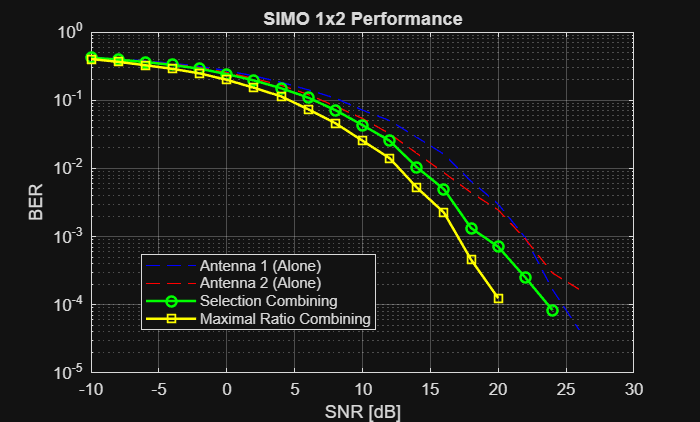

assumeTx1 = true;   % SIMO 1x2
applySIMOCombining =  true;

if (n_TXantenna == 1 || assumeTx1) && applySIMOCombining

    totalBER_MRC = zeros(1, length(SNRdB_vec));
    totalBER_SC  = zeros(1, length(SNRdB_vec));

    for SNR_idx = 1:length(SNRdB_vec)
        
        
       
        y1 = rxgrid{SNR_idx}{1, 1}; 
        h1 = Hhat_perfect{1, 1};
        y2 = rxgrid{SNR_idx}{2, 1}; 
        h2 = Hhat_perfect{2, 1};
        
      
        signal_combined = (conj(h1) .* y1) + (conj(h2) .* y2);
        
  
        power_norm = (abs(h1).^2 + abs(h2).^2);
        
        rxgrid_MRC = signal_combined ./ power_norm;
        
  
        rxdata_MRC = qamdemod(rxgrid_MRC, M, OutputType="bit");
        totalBER_MRC(SNR_idx) = sum(txdata ~= rxdata_MRC(:)) / length(txdata);


     
        power1 = abs(h1).^2;
        power2 = abs(h2).^2;
        

        mask1 = power1 > power2;
        mask2 = ~mask1;
        
     
        sig1_eq = rxgridEQ{SNR_idx}{1, 1};
        sig2_eq = rxgridEQ{SNR_idx}{2, 1};
        
        rxgrid_SC = (sig1_eq .* mask1) + (sig2_eq .* mask2);
        
    
        rxdata_SC = qamdemod(rxgrid_SC, M, OutputType="bit");
        totalBER_SC(SNR_idx) = sum(txdata ~= rxdata_SC(:)) / length(txdata);
    end

    % --- Plotting Results ---
    figure;
    semilogy(SNRdB_vec, totalBER_tx1rx1, 'b--'); hold on;
    semilogy(SNRdB_vec, totalBER_tx1rx2, 'r--');
    semilogy(SNRdB_vec, totalBER_SC, 'g-o', 'LineWidth', 1.5);
    semilogy(SNRdB_vec, totalBER_MRC, 'y-s', 'LineWidth', 1.5);
    hold off; grid on;
    xlabel('SNR [dB]'); ylabel('BER');
    legend('Antenna 1 (Alone)', 'Antenna 2 (Alone)', 'Selection Combining', 'Maximal Ratio Combining');
    title('SIMO 1x2 Performance');
    
legend(["Antenna 1 (Alone)", "Antenna 2 (Alone)", "Selection Combining", "Maximal Ratio Combining"], "Position", [0.2013 0.2183 0.3354, 0.1779])
end

**MIMO 2x2 Spatial Multiplexing**

Apply Spatial Multiplexing (SM) technique to allow the transmission of multiple data streams through the same radio channel.

apply_2x2MIMO_SM =  true;

if apply_2x2MIMO_SM
   
   %write code here
end

**Functions**

function [txgrid] = insertGaurdSubcarriers(txsymbols,n_occupied,nFFT) % Guard bands
    GuardCarriers_left = zeros(ceil((nFFT-n_occupied)/2), size(txsymbols,2)); 
    GuardCarriers_right = zeros(floor((nFFT-n_occupied)/2), size(txsymbols,2)); 
    txgrid = [GuardCarriers_left; txsymbols; GuardCarriers_right];
end

function [rxsymbols] = removeGaurdSubcarriers(rxgrid,n_occupied,nFFT)
    rxsymbols = rxgrid(ceil((nFFT-n_occupied)/2)+1:end-floor((nFFT-n_occupied)/2),:);
end

function txout = insertCP(tx_signal,nCP)
    txout = [tx_signal(end-nCP+1:end,:); tx_signal];
end

function rxgrid_inTime = removeCP(rxgrid_withCP,nCP)
    rxgrid_inTime = rxgrid_withCP(nCP+1:end,:);
end